close all
%   % Set the sampling frequency and bit depth
 fs = 48000; % Choose a suitable sampling frequency (e.g., 44.1 kHz)
 bitDepth = 16; % Choose a suitable bit depth (e.g., 16 bits)
 
% % Record the first voice segment
 recObj = audiorecorder(fs, bitDepth, 1); % 1 channel for mono recording
 disp('Start speaking for the first segment.');

Start speaking for the first segment.


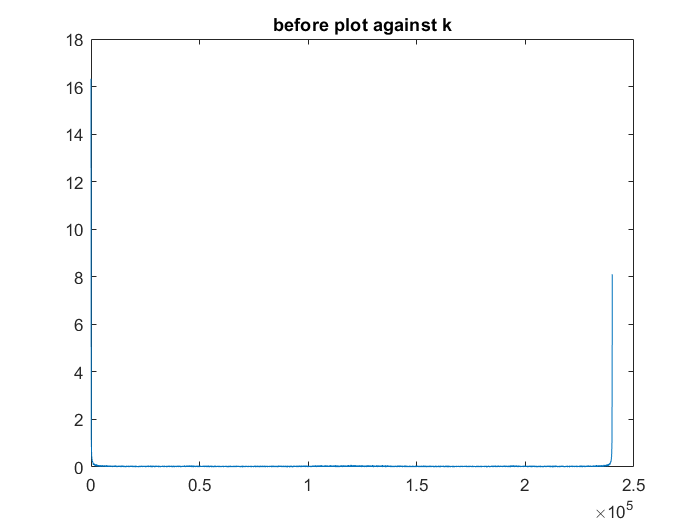

 recordblocking(recObj, 5); % Record for 10 seconds
 zaudio1 = getaudiodata(recObj);
audiowrite('input1.wav', zaudio1, fs); % Save the audio as 'input1.wav'

% % Record the second voice segment
% disp('Start speaking for the second segment.');
% recordblocking(recObj, 5); % Record for 10 seconds
% input2 = getaudiodata(recObj);
% audiowrite('input2.wav', input2, fs2); % Save the audio as 'input2.wav'
% %Audio Filtering

zaudiolength= length(zaudio1);
k = 0: zaudiolength-1;
ZaudioFD= fft (zaudio1,zaudiolength);
figure,plot(k, abs(ZaudioFD)),title ('before plot against k');%plot against k

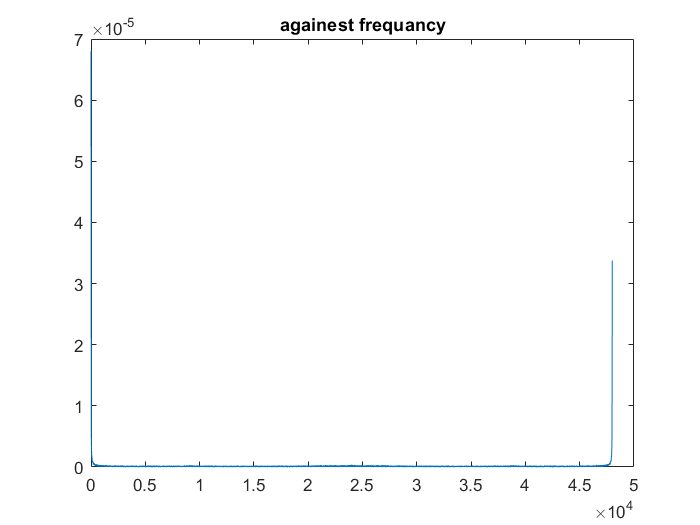

audiohz = (0 : zaudiolength - 1) * fs / zaudiolength;
figure,plot(audiohz, abs(ZaudioFD) / zaudiolength),title ('againest frequancy');%plot against freq

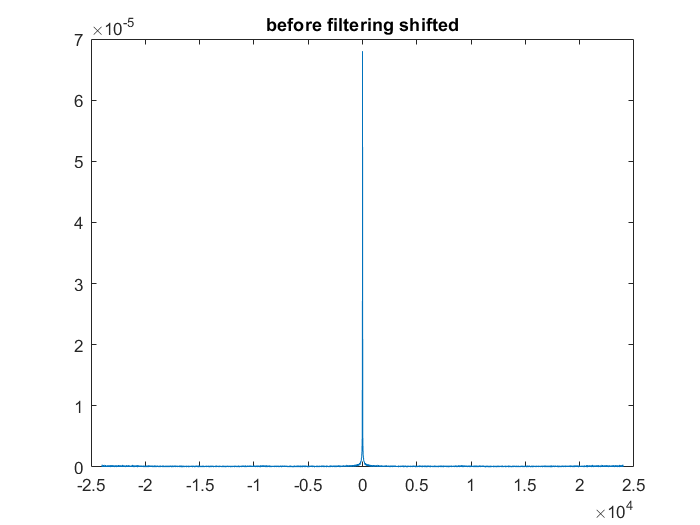

audioshift=(- zaudiolength/2 : zaudiolength/2 - 1)*fs /zaudiolength;
figure,plot(audioshift,abs(fftshift(ZaudioFD))/ zaudiolength), title ('before filtering shifted');%plot against freq hz after shift

zfiltered= filter(alo,zaudio1);

Unrecognized function or variable 'alo'.

zfilteredlength=length(zfiltered);
zfilteredFD=fft(zfiltered,zfilteredlength);
figure,plot(k,abs(zfilteredFD)), title('filtered againest k');
filterdshift=(- zaudiolength/2 : zaudiolength/2 - 1)*fs /zaudiolength;
figure,plot(filterdshift,abs(fftshift(zfilteredFD))/ zaudiolength), title ('after filtering shifted');%plot against freq hz after shift
playerf = audioplayer(zfiltered,fs);
playero = audioplayer(zaudio1,fs);
playblocking(playero);
playblocking(playerf);